# EE525 - Lab Project 1

Author: Grant Gallagher

Due: 10/8/2021

## Initialization

This section of code is used to clear the workspace of all variables and figures, so that the program can be run from scratch.

clc;    % Clear command window
clear;  % Clear all variables from workspace
clf;    % Clear all figures

## 1. Digital Communications

### 1.1 Introduction

In a phase-shift keyed (**PSK**) digital communication system,  a binary digit (also termed a bit), which is either a “**0**” or a “**1**”, is communicated to a receiver by sending either$\;s_0 =\textrm{Acos}\left(2\pi F_0 t+\pi \;\right)$ to represent a “0” or $s_1 =\textrm{Acos}\left(2\pi F_0 t\;\right)$ to represent a “1”, where $A>0$. The receiver that is used to decode the transmission is shown in the figure below. The receiver that is used to decode the transmission is shown in the figure below. 

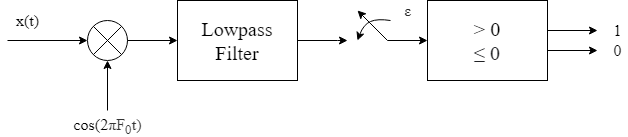

For this system, it is desired to send a signal of "0" or "1" to the receiver, which will then output a true binary value of 0 or 1. The input signal to the system is the noise corrupted signal which can be modeled by the following equation


$$x\left(t\right)=s_i \left(t\right)+w\left(t\right)$$


where $w\left(t\right)$ represents the channel noise and $s_i \left(t\right)$ represents a desired signal of either "0" or "1". Thus, the total input to the system can be represented by the sum of the two signals. 

Once the reference signal, $x\left(t\right)$, is sent to the receiver, it is multiplied by a constant periodic waveform of the same frequency, $\cos \left(2\pi F_0 t\right)$, and is passed through a lowpass filter. The result is a magnitude value which is proportional to the amplitude of the input signal. For example, it is desired to send a "1" to the system without any considering any channel noise,


$$\zeta ={\left\lbrack s_1 \left(t\right)\left(\cos \left(2\pi F_0 t\;\right)\right)\right\rbrack }^{\textrm{LPF}}$$


Then, we substitute the analog expression for $s_1 \left(t\right)$ as,

   
$$\zeta ={\left\lbrack \textrm{Acos}\left(2\pi F_0 t\;\right)\cos \left(2\pi F_0 t\;\right)\right\rbrack }^{\textrm{LPF}}$$


and taking the product of the terms results in

 
$$\zeta ={\left\lbrack {\textrm{Acos}}^2 \left(2\pi F_0 t\right)\right\rbrack }^{\textrm{LPF}}$$


Next, we can apply the identity of $\cos^2$ to give us


$$\zeta ={\left\lbrack \frac{A}{2}\left(1-\cos \left(4\pi F_0 t\right)\right)\right\rbrack }^{\textrm{LPF}}$$


and pull out the constant term


$$\zeta ={\frac{A}{2}\left\lbrack 1-\cos \left(4\pi F_0 t\right)\right\rbrack }^{\textrm{LPF}}$$


which results in a final value of 


$$\zeta =\frac{A}{2}$$


It can also be shown that a "0" input signal will result in $\zeta =-\frac{A}{2}$ since the phase of the input signal is offset by 180°. Subsequently, It can be shown that in the absence of noise, the output of the lowpass filter is,


$$\zeta =\left\lbrace \begin{array}{ll}
-\frac{A}{2} & \textrm{for}\;a\;"0"\\
\frac{A}{2} & \textrm{for}\;a\;"1"
\end{array}\right.$$


 To model the channel noise, we assume that the input to the receiver is the sum of the input signal and the channel noise. By the principle of superposition, we can determine that the actual value of $\zeta$ observed is


$$\zeta =\left\lbrace \begin{array}{ll}
-\frac{A}{2}+W & \textrm{for}\;a\;"0"\\
\frac{A}{2}+W & \textrm{for}\;a\;"1"
\end{array}\right.$$


where $W$ is the Gaussian random variable, $W~N\left(0,1\right)$. This means the random variable, $W$, follows a Gaussian distribution and has mean of 0 with a standard deviation of 1. After all this, the receiver decides if a "1" was transmitted if $\zeta >0$ and a "0" was transmitted if $\zeta \le 0$. The problem with this model is that the output signal may not coincide with the desired input signal. If a "1" is sent, the channel noise can disrupt the signal noise causing the output value to be flipped to a "0". The objective of this exercise is to analyze the probability of error, $P_e$, as a function of the input signal amplitude, $A$, using analytical and numerical methods.

### 1.2 Analytical Solution

In order to determine the probability of an error, we need to determine the probability of each instance. To do this, we must consider the conditional probabilities of error using Bayes' Theorem, which states that

   
$$P\left(A\left|B\right.\right)=\frac{P\left(B\left|A\right.\right)P\left(A\right)}{P\left(B\right)}$$


In this case, we want to identify the probability that error occurs, given the probability that a bit is sent. Thus, the probability that an error occurs when a "0" is sent can be represented by,


$$P_{e,0} =P\left(\textrm{error}\left|0\right.\right)P\left(0\right)$$


where the probability of a "0" being sent is 0.5. Likewise, the probability that an error occurs when a "1" is sent can be represented by,


$$P_{e,1} =P\left(\textrm{error}\left|1\right.\right)P\left(1\right)$$


where the probability of a "1" being sent is 0.5. Thus the total probability that an error occurs is equal to the sum of the total probabilities


$$P_e =P\left(\textrm{error}\left|0\right.\right)P\left(0\right)+P\left(\textrm{error}\left|1\right.\right)P\left(1\right)$$


To start, we can determine that


$$P\left(0\right)=P\left(1\right)=0\ldotp 5$$


because the sum of the total possibilities must add up to 1.

P_0 = 0.5; % Probability that a "0" is sent
P_1 = 0.5; % Probability that a "1" is sent

Next, we must calculate the conditional probabilities of error. Since $W$ is a Normal Gaussian random variable, it's [*Probability Density Function*](https://en.wikipedia.org/wiki/Probability_density_function) (PDF) can be described by the following equation


$$f_X \left(x\right)=\frac{1}{\sqrt{2\pi \;}}e^{-\frac{x^2 }{2}}$$


which is called the Normal Gaussian Probability Density function. Subsequently, we can substitute and substitute our receiver value, $\zeta$, for $X$ since the distribution of the random variable it is described by, $W$, is also a Normal Gaussian random variable. In this cause, the mean of the input signal is shifted by either $\frac{A}{2}$ or $-\frac{A}{2}$ depending on which bit is being sent. Thus, the PDF can be rewritten as


$$f_X \left(x\right)=\frac{1}{\sigma \sqrt{2\pi \;}}e^{-\frac{{\left(x-\mu \;\right)}^2 }{2}}$$


where $\mu \;$ is the mean of the distribution ($\pm \frac{A}{2}$), and $\sigma \;$ is the standard deviation of the distribution, which still remains as 1. Substituting these values into our PDF results in


$$f_{Z\;,0} =\frac{1}{\sqrt{2\pi \;}}e^{-\frac{{\left(w+\frac{A}{2}\right)}^2 }{2}} ,\;\;\;\;\;\textrm{for}\;\mathrm{a}\;\textrm{"0"}$$


for a "0" being sent, and


$$f_{Z,1} =\frac{1}{\sqrt{2\pi \;}}e^{-\frac{{\left(w-\frac{A}{2}\right)}^2 }{2}} ,\;\;\;\;\;\textrm{for}\;\mathrm{a}\;\textrm{"1"}$$


These two functions represent the new probability density functions for $\zeta$ for when a "0" or "1" is sent, respectively. The probability density function (PDF) is a function whose value at any given sample in the sample space can be interpreted as providing the relative likelihood that the value of the random variable would be close to that sample. 

syms A W zeta
Guass_Norm_pdf = 1/sqrt(2*pi) * exp((-(zeta)^2)/2); % Normal Gaussian Distribution func.
Zeta_0_pdf = subs(Guass_Norm_pdf, zeta, (W + A/2)); % PDF of a "0" being read
Zeta_1_pdf = subs(Guass_Norm_pdf, zeta, (W - A/2)); % PDF of a "1" being read

Subsequently another important function can be derive from the PDF. The [*Cumulative Distribution Function*](https://en.wikipedia.org/wiki/Cumulative_distribution_function) (CDF) is the probability that the random variable takes a value less than or equal to $x$, such that


$$F_X \left(x\right)=P\left\lbrace X\le x\right\rbrace$$


The CDF relates to the PDF of a random variable in that they have an integral/derivative relationship. That is, the integral of the PDF is equal to the CDF such that


$$F_X \left(a\right)=\int_{-\infty \;}^a f_X \left(x\right)\textrm{dx}$$


where $F_X \left(a\right)$ is the CDF evaluate at real value $a$. Additionally, the CDF has one important characteristic in that the minimum and maximum values range from 0 to 1. This means, that the integral (or area under the curve) of the PDF is equal to exactly one,


$$1=\int_{-\infty \;}^{\infty \;} f_X \left(x\right)\textrm{dx}$$


This property makes sense, since the total sum of probabilities within the sample space must add up to 1.

With regard to problem at hand, we can determine the likelihood of an error occurring by evaluating the CDF of the random variable for each case where the sent bit is equal to "0" and "1". In this case, we are calculating the probability of error given a conditioning event. Thus, we can derive the equation of the probability of error given that a "0" was sent as the integral of the PDF for all values where the read bit iz greater than 0. That is,


$$P\left(\textrm{error}\left|0\right.\right)=\int_0^{\infty \;} f_{Z,0} \left(\zeta \;\right)d\zeta$$


where the upper and lower bounds of the integral represent the bounds for the probability of where the read bit is equal to "1" (when it should have been "0"). Here, we can see the conditional probabilities for each case,

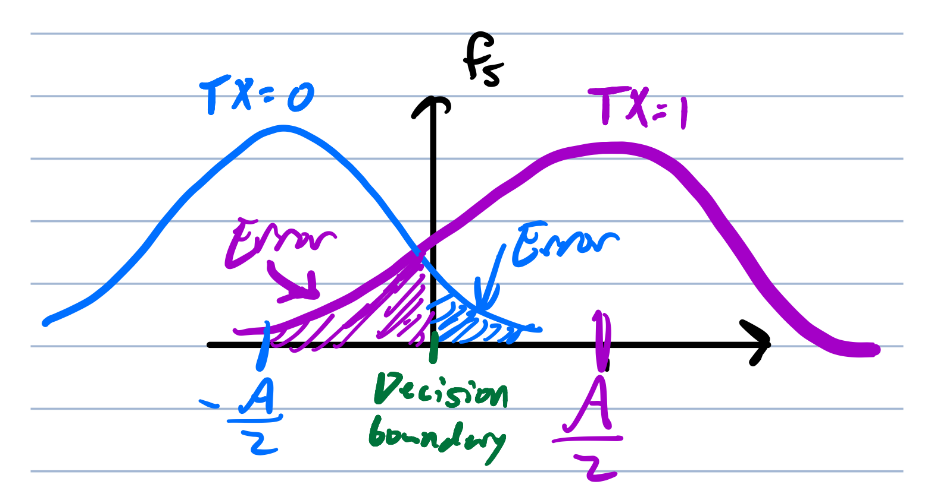

We can then substitute in our PDF function for $f_{Z,0} \left(\zeta \;\right)$,


$$P\left(\textrm{error}\left|0\right.\right)=\int_0^{\infty \;} \frac{1}{\sqrt{2\pi \;}}e^{-\frac{{\left(w+\frac{A}{2}\right)}^2 }{2}} \textrm{dw}$$


where $W$ is the only random variable. This may be confusing, however, A can be considered as a simple constant - making $W$ the only random variable we integrate with respect to. Subsequently, we can rearrange the terms to remove the constants from the integral, and also rearrange the exponent of the power term to all be within the square,


$$P\left(\textrm{error}\left|0\right.\right)=\left(\frac{1}{\sqrt{2\pi \;}}\right)\int_0^{\infty \;} e^{-{\left(\frac{w+\frac{A}{2}}{\sqrt{2}}\right)}^2 } \textrm{dw}$$


The reason why we rearrange the exponent term of the equation is to give it the similar form of the [*Error Function*](https://en.wikipedia.org/wiki/Error_function) (erf). The error function has the following form,


$$\textrm{erf}\left(z\right)=\frac{2}{\sqrt{\pi }}\int_0^{z\;} e^{-t^2 } \textrm{dw}$$


Translating the integral in to the respective error function form then yields


$$P\left(\textrm{error}\left|0\right.\right)=\left(\frac{1}{\sqrt{2\pi \;}}\right){\left\lbrack \left(\frac{\sqrt{\pi }}{\sqrt{2}}\right)\textrm{erf}\left(\frac{{\left(\frac{A}{2}+W\right)}}{\sqrt{2}}\right)\right\rbrack }_0^{\infty }$$


which has the same integration bounds as our original integral. Next, the coefficients in front of the error function can be move outside of the brackets, and the upper and lower bounds can be applied to reach the final closed-form solution,


$$P\left(\textrm{error}\left|0\right.\right)=\left(\frac{1}{2}\right)\left\lbrack 1-\textrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right\rbrack$$


which represents the probability of error, $P_0$, as a function $A$ given that a "0" was sent to the receiver. The conditional probability as a function of $A$ for a sent bit of "0" can be derived similarly as well. The differences in steps will be that the mean of the density function will negative, and the bounds of integration will be from $-\infty$ to $0$. Uncoincidentally, the probability of error as a function of $A$ given that the sent bit is "1" is exactly equal to that for the case where the sent bit is a "0",


$$P\left(\textrm{error}\left|1\right.\right)=\left(\frac{1}{2}\right)\left\lbrack 1-\textrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right\rbrack$$


Mathematically, we can achieve these results; however, this makes sense due to the face the both density functions are mirrored about the y-axis (zero) and share the same standard deviation. Thus, the likelihood of bad bits for each case is equal, given the same signal amplitude $A$.

P_e_given_0 = int(Zeta_0_pdf,W,0,inf); % CDF of an error given a "0"
P_e_given_1 = int(Zeta_1_pdf,W,-inf,0);     % CDF of an error given a "1"

Finally, the analytical solution to the total probability of error as a function of A can be expressed as


$$P_e =P\left(\textrm{error}\left|0\right.\right)\left(P\left(0\right)\right)+P\left(\textrm{error}\left|1\right.\right)\left(P\left(1\right)\right)$$


Plugging in the determined values for each element yields


$$P_e =\left(\frac{1}{2}\right)\left\lbrack 1-\textrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right\rbrack \left(0\ldotp 5\right)+\left(\frac{1}{2}\right)\left\lbrack 1-\textrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right\rbrack \left(0\ldotp 5\right)$$


then simplifying yield the final equation,


$$P_e =\left(\frac{1}{2}\right)\left\lbrack 1-\textrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right\rbrack$$


where $P_e$ is proportional to the amplitude of the input signal $A$. Subsequently, the closed-form solution of this probability function is also calculated in Matlab below.

% Probability of error as a function of A
P_e_analytical = vpa((P_e_given_0*P_0 + P_e_given_1*P_1), 4)

$$P\_e\_analytical = 0.5-0.5\,\mathrm{erf}\left(0.3536\,A\right)$$

### 1.3 Computer Simulation

Alternatively, we can use a computer simulation to plot $P_e$ versus $A$ to determine a numerical solution. To do this, we can initialize an array of value of $A$, which we can then take a specified number of samples of. First, we declare an array to contain values of $A$ ranging from 0 to 5, using 20 steps. Subsequently, we can also set the number of samples we would like for each value of $A$. As the sample size increases, variance in the mean will decrease and we will converge upon a solution that is almost identical to our analytical solution. Alternatively, a small samples size (n<100) will result in a mean probability of error that has a large variance. This means that our calculated probability of error may differ from our analytically determined solution for some samples.

Astep = 20;                         % Step size of A values
Aspan = [0, 5];                     % The minimum and maximum values for A
A_values = [Aspan(1):range(Aspan)/Astep:Aspan(2)];  % The array of A values
errors = zeros(length(A_values), 1);% An empty matrix containing the
                                    % simulated number of errors for given A value
n = 1000; % Sample Size    

With the range of $A$ values and sample size, $n$, we can now simulate the random process. For each value of $A$, we will assign an array containing $n$ values of $\frac{A}{2}+W$ where $W$ is the a Normal Gaussian random variable with a mean of 0 and standard deviation of 1. For each value of $A$, we count the total instances of error ($W+\frac{A}{2}\le 0$ or $W-\frac{A}{2}\ge 0$) and divide that number by the total number of samples. This final value will yield us the expected value of the probability of error for any given value of $A$.

% Iterate through each value of A                             
for k = 1:length(A_values)
    dist = normrnd(A_values(k)/2, 1, [1 n]); % Distribution of read values for A
    % Iterate through each sample of read values.
    for m = 1:n
        % Determine if the received value is an error
        if dist(m) <= 0
            errors(k) = errors(k) + 1; % Count the number of errors.\
        end
    end
end
P_e_simulation = errors/n; % Probability of error vs A

With the array of expected values of the probability of error for specified values of $A$, we can then plot the results.

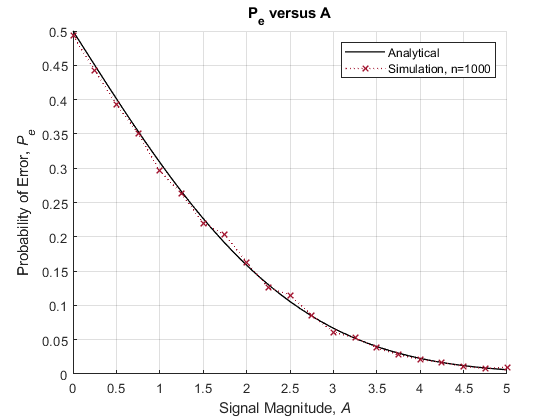

fig1 = figure; % Create a new figure
hold on
% Plot the analytical solution
fplot(P_e_analytical, '-', 'Color', [0 0 0] ...
                         , 'LineWidth', 1 ...
                         , "XRange", [0 5])

% Plot the simulation for n=100 
plot(A_values, P_e_simulation, ':', 'Color', [0.6350 0.0780 0.1840] ...
                                  , 'LineWidth', 1 ...
                                  , 'Marker', 'x')
hold off

% Label the graph appropriately
legend('Analytical', 'Simulation, n=1000')
title("P_e versus A")
xlabel("Signal Magnitude, {\itA}  ")
ylabel("Probability of Error, {\itP_e}")
grid on

shg % Show the Figure

From the plot above, we can see the numerical and analytical solutions agree with one another. Though they do not align perfectly, increasing the sample size of the simulation will cause the numerical solution to converge upon the analytical solution. The sample size was chosen to demonstrate a subtle difference between solution methods and to distinguish on the figure.

From the trend, we can see that the probability of error,$P_e$, *decreases* for large values of $A$. This is expected due to the fact that if we increase the magnitude of the input the signal, the effect of the that the random Gaussian noise, $W$, has on the signal decreases. As the limit of the magnitude of the input signal approaches infinity, the probability of a error goes to zero,


$$\underset{A\to \infty \;}{\mathrm{lim}} P_e \left(A\right)=0$$


Another interesting feature of this plot is that the probability of error when $A$ is equal to zero approaches 0.5. At this point, the probability of error has the same distribution as the random variable, $W$, which is a Normal Gaussian distribution (centered at 0 with a standard deviation of 1). Thus, without any input signal amplitude $A$, the PDF of the receiver becomes the same as the for a Normal Gaussian variable (which is what $W$ is).

### 1.4 Discussion

With this information, we can analytically/numerically determine receiver gain values, $A$, such that the probability of error is limited. For example, let's design a signal such that the probability of error $P_e$ does not exceed 0.01. That is, we can expect that we will only lose 1 bit of information for every 100 bits sent (assuming that we have a very large sample size). First, let's determine an solution using our analytical function. The problem constraint can be expressed by the following equation,


$$P_e \left(A\right)\le 0\ldotp 01$$


where $P_e \left(A\right)$ is our analytically determined solution to $P_e$ as a function of $A$. We then then substitute our equation,


$$\frac{1}{2}\left(1-\textrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\right)\le 0\ldotp 01$$


then, multiplying both sides by 2


$$1-\textrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\le 0\ldotp 02$$


then, subtracting 1 from both sides while keeping $A$ on the left hand side,


$$\textrm{erf}\left(\frac{\sqrt{2}}{4}A\right)\le 0\ldotp 98$$


and taking the inverse error function of both sides,


$$\frac{\sqrt{2}}{4}A\le {\textrm{erf}}^{-1} \left(0\ldotp 98\right)$$


isolating A to the left hand side of the equation


$$A\le 2\sqrt{2}{\textrm{erf}}^{-1} \left(0\ldotp 98\right)$$


and finally, evaluating the inverse error function and square root for the numerical approximation,


$$A\ge 4\ldotp 653$$


A_min = vpa(solve(0.01 == P_e_analytical,A), 4) % Minimum value of A such P_e <= 0.01

$$A\_min = 4.653$$

Alternatively, we can also find the solution to this problem using our numerical simulation results. We can determine the value of $A$ such that $P_e \le 0\ldotp 01$ by finding the value at which $P_e \left(A\right)$ is equal to 0.01. That is, we can draw a horizontal line at $P_e =0\ldotp 01$ until we reach our function, and then draw a vertical line down to find $A_{\min }$. We zoom in on the plot and show this method graphically as follows,

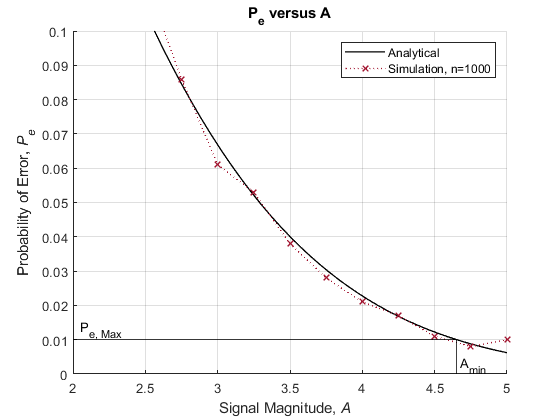

fig2 = fig1;
hold on
plot([double(A_min), double(A_min)], [0, 0.01], 'Color', [0 0 0])
plot([0, double(A_min)], [0.01 0.01], 'Color', [0 0 0])
text(2.05, 0.013, 'P_{e, Max}')
text(double(A_min)+0.02, 0.0025, 'A_{min}')
xlim([2 5])
ylim([0 0.1])
grid on
hold off
legend('Analytical', 'Simulation, n=1000')

shg % Show the Figure

Thus, it is very easy to see on the graph that at 0.01, the value of $A_{\min }$ is roughly equal to 4.6

## 2. COVID-19 Data Analysis

### 2.1 Background

In this exercise, we will analyze the data provided by [Our World in Data](https://github.com/owid/covid-19-data/tree/master/public/data) to understand the Coronavirus pandemic. In particular, we will study the factors that might impact the mortality rate of COVID-19. Our World in Data provides daily numbers on confirmed cases and deaths, testings, vaccinations, and other metrics for over 100 countries. For this study, we will consider the following data: *new_deaths_per_million* for the month of September 2021, *new_tests_per_thousand* for the same period, *people_vaccinated_per_hundred*, *aged_70_older*, *gdp_per_capita, cardiovasc_death_rate, diabetes_prevalence*. While there are many countries that are included within this data, we will only be considering the data from countires which contain at least one value for *each* of the random variables aformentioned. That is, if a country contains valid data for every variable but one - for example, no data on diabetes prevelence - then it will be *excluded* from this analysis.

With this extensive amount of data, there are a variety of trends, properties, and correlations that we can discover behind Covid-19 related deaths; such as whether having diabetes is linked to an increase risk of dying from Covid-19, or whether a country with a high GDP is linked to more or less Covid-19 related death. Subsequently, we can also determine mean and distributions of all of the random variables for each country. Data and statistics can give us a powerful insight on how different factors are interconnected with one another.

### 2.2 Import and Filtering Data

First, we must import the most recent data from comma separated variable (csv) file provided by Our World in Data. Next, we can identify a list of all of the unique country names.

raw_covid_data = readtable('owid-covid-data.csv'); % Table of raw covid data
unique_countries = unique(raw_covid_data.location); % Unique country names

Now comes the tricky part. For this study, we reject and all countries that do not contain data for any of the listed random variables. That is, *each country must have at least one distinct value for every random variable* under consideration. To do this, we can create an empty array which will contain the values of all unique countries that fit this rule. Next, check whether the country has at least one data point for every random variable. If the country does not contain an empty or null array of values for each random variable, we accept it and append it to a list of countries which fit this category. 

countries = cell(1);
% Aquire data for each country with valid data
for k = 1:length(unique_countries)
    % Filter by month and valid values
    if or(isempty(raw_covid_data.new_deaths_per_million( ...
            ...
            string(raw_covid_data.location) == unique_countries(k) ...
                ...
                & raw_covid_data.date >= '1-Sep-2021' ...
                & raw_covid_data.date <= '30-Sep-2021')) ...
       , all(isnan(raw_covid_data.new_deaths_per_million( ...
            string(raw_covid_data.location) == unique_countries(k) ...
                & raw_covid_data.date >= '1-Sep-2021' ...
                & raw_covid_data.date <= '30-Sep-2021'))))
        continue
    % Filter by month and valid values                                    
    elseif or(isempty(raw_covid_data.new_tests_per_thousand( ...
                             string(raw_covid_data.location) == unique_countries(k) ...
                             & raw_covid_data.date >= '1-Sep-2021' ...
                             & raw_covid_data.date <= '30-Sep-2021')) ...
           , all(isnan(raw_covid_data.new_tests_per_thousand( ...
                             string(raw_covid_data.location) == unique_countries(k) ...
                             & raw_covid_data.date >= '1-Sep-2021' ...
                             & raw_covid_data.date <= '30-Sep-2021'))))
        continue
    % Filter by valid values
    elseif or(isempty(raw_covid_data.people_vaccinated_per_hundred( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.people_vaccinated_per_hundred( ...
                string(raw_covid_data.location) == unique_countries(k))))
       continue 
    % Filter by valid values   
    elseif or(isempty(raw_covid_data.aged_70_older( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.aged_70_older( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    % Filter by valid values    
    elseif or(isempty(raw_covid_data.gdp_per_capita( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.gdp_per_capita( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    % Filter by valid values
    elseif or(isempty(raw_covid_data.cardiovasc_death_rate( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.cardiovasc_death_rate( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    % Filter by valid values
    elseif or(isempty(raw_covid_data.diabetes_prevalence( ...
                string(raw_covid_data.location) == unique_countries(k))) ...
           , isnan(raw_covid_data.diabetes_prevalence( ...
                string(raw_covid_data.location) == unique_countries(k))))
        continue
    end
    % Append country name to list of countries with valid data
    countries(end+1,1) = unique_countries(k);
end
countries = string(countries(2:end)); % Remove the first, null index

### 2.3 Distributions of Random Variables

Before we plot the distribution of random variables for each country, we must first determine collect samples values for each county. In this study, we will take the *average* value of each random variable **except for vaccination rates**. We will be comparing the distribution of random variables by country; thus, each country will be represented by a single value for each random variable. However, since vaccination rates do not go down (unless individuals die, move out of the country, or miraculously become unvaccinated again) we will only consider the most recent vaccination rate.

To gather the samples of random variables, we first initialize empty arrays for each variable which are the lengths of the number of countries which are included in this study. Then, for each country, we iterate the table of data to extract the average value of each random variable. The result will be a table that is the size of [(# countries) x (# random variables)].

% Distributions of random variables
dist_avg_deaths_per_million = zeros(length(countries), 1);
dist_avg_tests_per_thousand = zeros(length(countries), 1);
dist_people_vaccinated_per_hundred = zeros(length(countries), 1);
dist_avg_aged_70_older = zeros(length(countries), 1);
dist_avg_gdp_per_capita = zeros(length(countries), 1);
dist_avg_cardiovasc_death_rate = zeros(length(countries), 1);
dist_avg_diabetes_prevalence = zeros(length(countries), 1);
for k = 1:length(countries)
    new_deaths_per_million = raw_covid_data.new_deaths_per_million( ...
                                string(raw_covid_data.location) == countries(k) ...
                                & raw_covid_data.date >= '1-Sep-2021' ...
                                & raw_covid_data.date <= '30-Sep-2021' ...
                                & ~isnan(raw_covid_data.new_deaths_per_million));
                                        
    new_tests_per_thousand = raw_covid_data.new_tests_per_thousand( ...
                                string(raw_covid_data.location) == countries(k) ...
                                & raw_covid_data.date >= '1-Sep-2021' ...
                                & raw_covid_data.date <= '30-Sep-2021' ...
                                & ~isnan(raw_covid_data.new_tests_per_thousand));
                            
    dist_people_vaccinated_per_hundred(k) = max( ...
                             raw_covid_data.people_vaccinated_per_hundred( ...
                             string(raw_covid_data.location) == countries(k) ...
                             & ~isnan(raw_covid_data.people_vaccinated_per_hundred)));

    aged_70_older = raw_covid_data.aged_70_older( ...
                    string(raw_covid_data.location) == countries(k) ...
                    & ~isnan(raw_covid_data.aged_70_older));
                                
    gdp_per_capita = raw_covid_data.gdp_per_capita( ...
                     string(raw_covid_data.location) == countries(k) ...
                     & ~isnan(raw_covid_data.gdp_per_capita));
    
    cardiovasc_death_rate = raw_covid_data.cardiovasc_death_rate( ...
                            string(raw_covid_data.location) == countries(k) ...
                            & ~isnan(raw_covid_data.cardiovasc_death_rate));
    
    diabetes_prevalence = raw_covid_data.diabetes_prevalence( ...
                          string(raw_covid_data.location) == countries(k) ...
                          & ~isnan(raw_covid_data.diabetes_prevalence));
    
    
    dist_avg_deaths_per_million(k) = first_moment(new_deaths_per_million);
    dist_avg_tests_per_thousand(k) = first_moment(new_tests_per_thousand);
    dist_avg_aged_70_older(k) = first_moment(aged_70_older);
    dist_avg_gdp_per_capita(k) = first_moment(gdp_per_capita);
    dist_avg_cardiovasc_death_rate(k) = first_moment(cardiovasc_death_rate);
    dist_avg_diabetes_prevalence(k) = first_moment(diabetes_prevalence);
end
distributions = [dist_avg_deaths_per_million, dist_avg_tests_per_thousand, ...
                 dist_people_vaccinated_per_hundred,dist_avg_aged_70_older, ...
                 dist_avg_gdp_per_capita, dist_avg_cardiovasc_death_rate, ...
                 dist_avg_diabetes_prevalence];
random_variable_names = {'Avg. New Deaths per Million','Avg. New Tests per Thousand',...
                         'People Vaccinated Per Hundred', 'Avg. Aged 70 or Older', ...
                         'Avg. GDP per Capita', 'Avg. Cardiovascular Death Rate', ...
                         'Avg. Diabetes Prevalence'};

% The total collected of average values (max. vaccination rates) for each country          
table_distributions = array2table(distributions, 'RowNames',countries, ...
                                     'VariableNames', random_variable_names);

### 2.4 Calculating the Means and variances

Since we are dealing with a discrete sample, we will use discrete equations to calculate the means, variances, and correlation coefficients for each random variable. To begin the [mean](https://en.wikipedia.org/wiki/Mean) - also called the expected value - can be thought of as the average or center of the expected average outcome over many samples. That is, if you take a large sample of data, a majority of the data will lie closer to the mean. The discrete mathematical expression for the mean is


$$\mu_x =E\left(X\right)=\sum_x \left(x\right)p\left(x\right)$$


where$\;\mu_x$ and $E\left(X\right)$ are the mean (expected value). In this case, we don't know the probability of each sample happening, so we can simply reconsider the expression as,


$$\mu_x =E\left(X\right)=\frac{\sum_x x}{n_x }$$


where the mean can be expressed as the sum of the values of each sample divided by the number of samples.

Subsequently, the variance of a random variable is defined as the spread around the mean. The variance can be expressed as,


$$\sigma^2 =\textrm{Var}\left(X\right)=E\left\lbrack {\left\lbrack X-E\left(X\right)\right\rbrack }^2 \right\rbrack$$


Where $\sigma$ is the standard deviation and $\sigma^2$ is the variance. However, this expression can be simplified even further, since the expectation is a linear operator. We can distribute the terms to arrive at this easier-to-implement equation,


$$\sigma^2 =\textrm{Var}\left(X\right)=E\left\lbrack X^2 \right\rbrack -\mu_x^2$$


Where $E\left\lbrack X^2 \right\rbrack$ is defined as the second moment. Subsequently, taking the square root of the variance will yield the standard deviation, which is also helpful for describing the spread of data about the mean. While the calculations for the means variances are done below, the tables are displayed in section 2.6 alongside the random variables' histograms so that they are easier to refer to.

table_averages = array2table(first_moment(table_distributions), ...
                                        'RowNames', {'Global Averages'}, ...
                                        'VariableNames', random_variable_names);
table_variances = array2table(variance(table_distributions), ...
                                        'RowNames', {'Global variances'}, ...
                                         'VariableNames', random_variable_names);

### 2.5 Analysis of Death Rates

Perhaps the most talked about statistic regarding Covid-19 is it's death rate. The death rate will vary from country to country, depending on various geological, socioeconomical, and various other factors. Here, we can see a histogram of the average death rate by country.

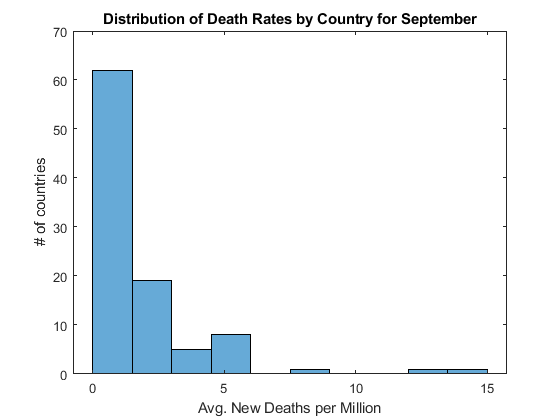

fig3 = figure;
histogram(dist_avg_deaths_per_million, round(sqrt(length(countries))))
title('Distribution of Death Rates by Country for September')
ylabel('# of countries')
xlabel('Avg. New Deaths per Million')

In the histogram above, the location of each bin along the x-axis represents the average death rate. The height of each bin along the y-axis represents the number of countries that fall within the left and right hand bin limits. For example, the first pin depicts that there are 62 countries which have less than 1.5 deaths per million people - which is pretty low. Alternatively, we can see from the two bins on the right that there is one country that has between 12-13.5 deaths per million people, and another country which has between 13.5-15 deaths per million people. Remember, these are average death rates for the month of September only. The histogram also shows us that the distribution of average death rates by country is unimodal and skewed to the right. This means that there are a lot of countries which have relatively low death rates, with a few outliers with relatively high death rates.

The mean, variance, and standard deviation of average death rates for the month of September are equal to 1.80, 5.97, and 2.44 deaths per million people respectively.

### 2.6 Analysis of Other Random Variables

Additionally, we can plot the histogram for every other random variable considered in this study as well. To save space and paper size, two plot containing subplots of histograms for all 6 random variables are shown below.

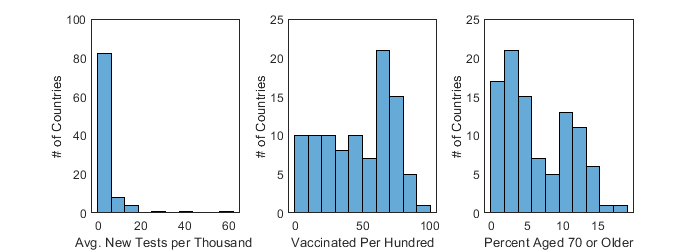

fig4 = figure;
set(gcf, 'position', [0 0 700 250])
subplot(1, 3, 1)
histogram(table_distributions.("Avg. New Tests per Thousand"), ...
                                round(sqrt(length(countries))))
xlabel('Avg. New Tests per Thousand ')
ylabel('# of Countries')
subplot(1, 3, 2)
histogram(table_distributions.("People Vaccinated Per Hundred"), ...
                                round(sqrt(length(countries))))
xlabel('Vaccinated Per Hundred')
ylabel('# of Countries')
subplot(1, 3, 3)
histogram(table_distributions.("Avg. Aged 70 or Older"), ...
                                round(sqrt(length(countries))))
xlabel('Percent Aged 70 or Older')
ylabel('# of Countries')

**Average Rate of New Tests**

Starting with the average number of new tests per thousand people (for the month of Sept.), we can see that the distribution is similar to that of the average death rates (for Sept.). The distribution is unimodal and skewed to the right. There are countries which may be possible outliers which have very high testing rates of greater than 40 per thousand. The mean was calculated to be 4.12 new tests per thousand people, which is relatively low. The variance and standard deviation is relatively high with values of 67.08 and 8.19 respectively.

**Vaccination Percentages**

This distribution is perhaps the most unusual. There appear to be a flat-line of vaccination rates per counter between 0 and 50 percent. Most countries have vaccination rates that lie between 60 and 70 percent, and there is only one country that has a vaccination rate greater than 90 percent. The mean vaccination rate is equal to 47.0 percent, and the variance and standard deviation are 643.7 and 25.4 percent respectively. It's clear to see that this extremely large spread in vaccination rates in the histogram equates to a large variance/standard deviation.

**Percent of People 70 or Older**

The distribution of the percent of people aged 70 or older among countries appear to be bimodal. There are two distinct peaks occurring at approximately 2.5 and 11.5 percent. Perhaps this could be do to a great divide in elderly care, nutrition, or some other factor such as GDP. The reason cannot be determined by this plot, and more statistical analysis would need to be performed. The largest percentage of citizens aged 70 or older for a given country is 18 percent. The mean of the samples is 6.6 percent with a variance of 20.6 and standard deviation of 4.5. While there are two distinct peaks, we would need to implement alternative statistical methods to find out more about this distribution. However, we can for a fact say that the spread of data is large.

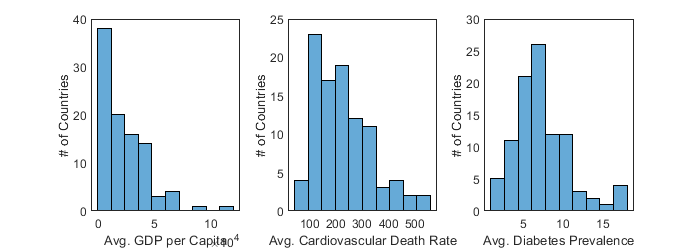

fig5 = figure;
set(gcf, 'position', [0 0 700 250])
subplot(1, 3, 1)
histogram(table_distributions.("Avg. GDP per Capita"), ...
                                round(sqrt(length(countries))))
xlabel('Avg. GDP per Capita')
ylabel('# of Countries')
subplot(1, 3, 2)
histogram(table_distributions.("Avg. Cardiovascular Death Rate"), ...
                                round(sqrt(length(countries))))
xlabel('Avg. Cardiovascular Death Rate')
ylabel('# of Countries')
subplot(1, 3, 3)
histogram(table_distributions.("Avg. Diabetes Prevalence"), ...
                                round(sqrt(length(countries))))
xlabel('Avg. Diabetes Prevalence')
ylabel('# of Countries')

**Average GDP Per Capita**

The distribution of the gross domestic product (GDP) appears unimodal and skewed to the right. The data does not seem to have as great of a spread as the distribution of death rates or new tests (Sept.). Nonetheless, there is one country that stands out with a GDP of more than 10e4. The mean value of this distribution is 23,753 and the variance and standard deviation are 4.392e8 and 20958 respectively.

**Average Cardiovascular Death Rate**

Cardiovascular death rate is a very interesting population parameter that could play large effect on the impact of individuals with Covid-19. There have been many reports that Covid-19 leaves victims with long term heart defects such as inflammation. The distribution of data is clearly unimodal, but skewed to the right slightly. The mean value of cardiovascular death rates is 225 and the variance and standard deviation are 11509 and 107 respectively. 

**Average Diabetes Prevalence**

The prevalence of diabetes can also be a significant factor in the impact that Covid-19 has on individuals. Covid-19 attacks and weakens the immune system, causing the body to fight and spend resources that individuals with diabetes may have trouble with. The general shape of this distribution is unimodal; however, there is a small mode located on the high end of diabetes prevalence. Subsequently, the mean, variance, and standard deviation for the average cardivascular prevalence are 7.4, 11, and 3.3 respectively.

### **2.7 Tabular Results for Means and variances of Metrics.**

In addition to the discussion of the distributions in the previous section, two tables containing the mean and variances for each random variable is listed below.

disp(table_averages)

                       Avg. New Deaths per Million    Avg. New Tests per Thousand    People Vaccinated Per Hundred    Avg. Aged 70 or Older    Avg. GDP per Capita    Avg. Cardiovascular Death Rate    Avg. Diabetes Prevalence
                       ___________________________    ___________________________    _____________________________    _____________________    ___________________    ______________________________    ________________________

    Global Averages              1.8016                         4.1216                          47.014                       6.5844                   23753                       225.08                         7.4159         



disp(table_variances)

                        Avg. New Deaths per Million    Avg. New Tests per Thousand    People Vaccinated Per Hundred    Avg. Aged 70 or Older    Avg. GDP per Capita    Avg. Cardiovascular Death Rate    Avg. Diabetes Prevalence
                        ___________________________    ___________________________    _____________________________    _____________________    ___________________    ______________________________    ________________________

    Global variances              5.9724                          67.08                          643.67                       20.626                4.3923e+08                     11509                          10.988         



### 2.8 Correlations Between Death Rates and Other Metrics

Now, we will analyze the correlations between the average death rates per million people for the month of September and each other metric. The correlation (or dependence) can be described as the statistical relationship between two random variables. That is, higher correlation values result in a positive relationship - the magnitude of one random variable increases with respect to another random variable. If two random variables have a negative correlation, then the magnitude of one random variable decrease with respect to another. If the correlation is relatively close to zero, then it can be said that there is no correlation. However, *no correlation does not mean that the two random variables are independent.* The correlation between two random variables can be expressed as,


$$R_{\textrm{XY}} =E\left\lbrack \textrm{XY}\right\rbrack =\int_{-\infty }^{\infty } \int_{-\infty }^{\infty } {\textrm{xyf}}_{\textrm{xy}} \left(x,y\right)\textrm{dxdy}$$


where $X$ and $Y$ are two random variables and $f_{\textrm{xy}} \left(x,y\right)$ is the joint probability density function. A table of the correlation coefficients between death rates (Sept.) and the other random variables  is calculated and displayed below.

Correlations = round(corrcoef(table2array(table_distributions)),3);
table_correlations = array2table(Correlations(1,2:end), ...
                                'VariableNames', random_variable_names(2:end));
disp(table_correlations)

    Avg. New Tests per Thousand    People Vaccinated Per Hundred    Avg. Aged 70 or Older    Avg. GDP per Capita    Avg. Cardiovascular Death Rate    Avg. Diabetes Prevalence
    ___________________________    _____________________________    _____________________    ___________________    ______________________________    ________________________

               0.001                          -0.118                        0.107                  -0.134                       0.241                          0.205          



From the correlation values, there are no random variables that have a *strong* correlation with death rates. The test rates has zero correlation with death rates, whereas the vaccination rates, rates of people over 70 years old, and GDP per capita are insignificant. The only metrics which can be considered to have a weak correlation to death rates are the cardiovascular death rates and diabetes prevalences. One could hypothesize that these two factors would be correlated with Covid-19 death rates, since underlying health conditions have been proven to have a correlation serious Covid-19 implications. Subsequently, we can visualize the scatterplots of these variables against the death rates.

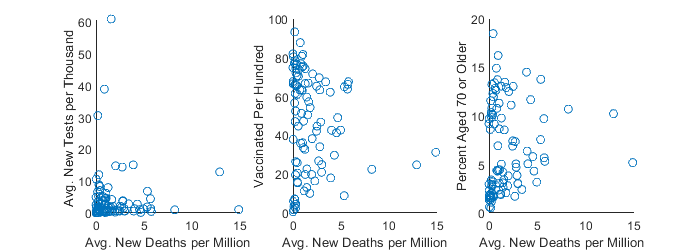

fig6 = figure;
set(gcf, 'position', [0 0 700 250])
subplot(1, 3, 1)
scatter(dist_avg_deaths_per_million, dist_avg_tests_per_thousand)
xlabel('Avg. New Deaths per Million')
ylabel('Avg. New Tests per Thousand ')
subplot(1, 3, 2)
scatter(dist_avg_deaths_per_million, dist_people_vaccinated_per_hundred)
xlabel('Avg. New Deaths per Million')
ylabel('Vaccinated Per Hundred')
subplot(1, 3, 3)
scatter(dist_avg_deaths_per_million, dist_avg_aged_70_older)
xlabel('Avg. New Deaths per Million')
ylabel('Percent Aged 70 or Older')

As we saw with the correlation coefficients, there is hardly any correlation between the plots shown above. There are a few potential outliers that can be visualized in the plot of test rates and death rates, but we would have to consider how many standard deviations they are from the mean in order to confirm. However, there is one subtle characteristic among these plots that can pique are interest. We confirmed that there is a negative (weak) correlation between vaccination rates and mortality rates. This means that mortality rates decrease as the percentage of vaccinated populations increase, and vise versa. However, one can not say the correlation is equal to causation.

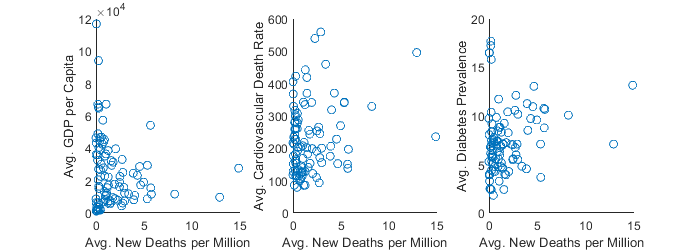

fig7 = figure;
set(gcf, 'position', [0 0 700 250])
subplot(1, 3, 1)
scatter(dist_avg_deaths_per_million, dist_avg_gdp_per_capita)
xlabel('Avg. New Deaths per Million')
ylabel('Avg. GDP per Capita')
subplot(1, 3, 2)
scatter(dist_avg_deaths_per_million, dist_avg_cardiovasc_death_rate)
xlabel('Avg. New Deaths per Million')
ylabel('Avg. Cardiovascular Death Rate')
subplot(1, 3, 3)
scatter(dist_avg_deaths_per_million, dist_avg_diabetes_prevalence)
xlabel('Avg. New Deaths per Million')
ylabel('Avg. Diabetes Prevalence')

While GDP per capita showed a relatively insignificant correlation coefficient, it did show a weak negative correlation. This means that there is something (albeit small) thing to be said about rich vs poor countries when it comes to mortality rates. Richer countries have slightly less mortality rates compared to poorer countries. However, there are also many other factors which can counteract this correlation. One example is that richer countries tend to have more urban infrastructure such as public transport and close-living quarters. Both of these factors could increase the positive rate of Covid-19. Alternatively, one could also argue that richer countries also have better access to technology and medicine, making their mortality rates less. The point is that we cannot say that correlation is equal to causation.

Now, we can visualize the very weak correlation between preexisting medical conditions and Covid-19 death rates. Cardiovascular death rates showed a correlation coefficient of 0.241 and diabetes prevalence showed a correlation coefficient of 0.205. While both show a positive correlation with mortality rates, cardiovascular death rates is the most significant factor that affect mortality rate. Cardiovascular is a term that refers to circulatory system which carries blood, nutrients and oxygen to various parts of the body. If an individual with a cardiovascular condition or heart disease were to get Covid-19, they would suffer more damage due to the fact that their body already has a difficult time transporting oxygen throughout the body. With Covid-19, their respiratory system is affected which exacerbates their symptoms and could result in a higher mortality rate.

## 3. Reflection

This study was an excellent opportunity for me to establish a grasp of the concepts learn in lecture. I have two statistics classes in the past, but both of those classes took a very different approach. So far, this class has been more than just a refresher. Being able to analyze real world problems in a dynamic approach through programming is extremely rewarding because I am able to manipulate the parameters and witness the effects in real time. Additionally, having to write out the expressions and solution process both analytically and numerically helps solidify the concepts in my mind. They say that the best way to learn is to teach - which is why I feel like I am "teaching" these subjects as I am writing it.

As for the two subjects present in this lab, I really enjoyed them both. The first subject, analyzing a digital comms. system, was very interesting because I got to solve the problem analytically and verify my results with a simulation. There is something very rewarding about having answers match up. Subsequently, it was also very cool to see how different sample sizes affected the distribution of the probability of error. As the sample sizes increased, the variance decreased and the numerical solution converged onto the analytical solution. I also really enjoyed the second subject because it was focused around real world data. However, there were so much data that running the script could sometimes take ages. In the future, I think that the learning objective can come across the same way even if a smaller amount of data is used. However, using a large set of data forces oneself to resort to programming methods to do the heavy work.

The results from the Covid-19 analysis also match up with my intuitions. I suspected that preexisting medical conditions like heart disease and diabetes would positively correlate with Covid-19 mortality rates. Likewise, I hypothesized the GDP and vaccinated rates would negatively correlate. What was surprising to see was that there was absolutely no correlation between testing rates and mortality rates. I was also surprised to see how weak the correlations are between the random variables.

Overall, this lab was really enjoyable.

## 4. Appendices

### 4.1 Table of Distributions by Country

disp(table_distributions)

                              Avg. New Deaths per Million    Avg. New Tests per Thousand    People Vaccinated Per Hundred    Avg. Aged 70 or Older    Avg. GDP per Capita    Avg. Cardiovascular Death Rate    Avg. Diabetes Prevalence
                              ___________________________    ___________________________    _____________________________    _____________________    ___________________    ______________________________    ________________________

    Argentina                             2.4609                       0.60317                          65.36                        7.441                     18934                     191.03                           5.5          
    Armenia                    

### 4.2 Mean Function

function mu = first_moment(S)
    if iscolumn(S)
        mu = sum(S)/length(S);
    else
        mu = zeros(1, width(S));
        for n = 1:length(mu)
            mu(n) = sum(S{:,n})/length(S{:,n});
        end
    end
end

### 4.3 Variance Function

function sigma_2 = variance(S)
    if iscolumn(S)
        sigma_2 = sum((S-first_moment(S)).^2)/(length(S)-1);
    else
        sigma_2 = zeros(1, width(S));
        for n = 1:length(sigma_2)
            rv = table2array(S(:,n));
            rms = zeros(length(rv),1);
            for m = 1:length(rms)
                rms(m) = (rv(m)-first_moment(rv))^2;
            end
            sigma_2(1,n) = sum(rms)/(length(rv)-1);
        end
    end
end